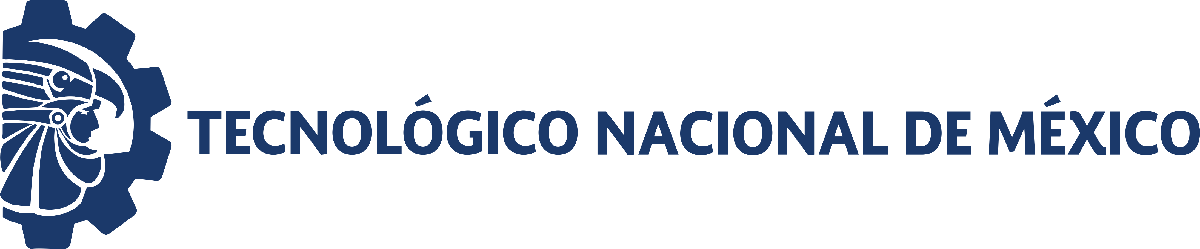                                 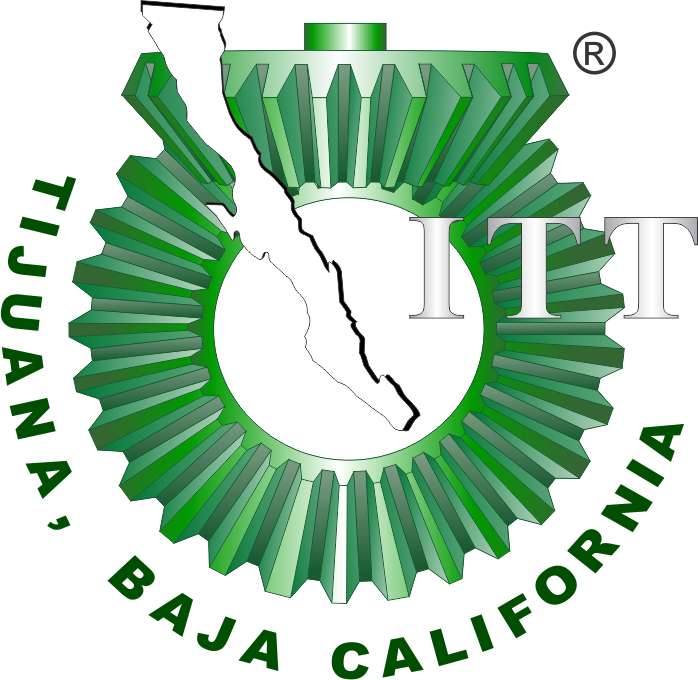

# Práctica 3: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

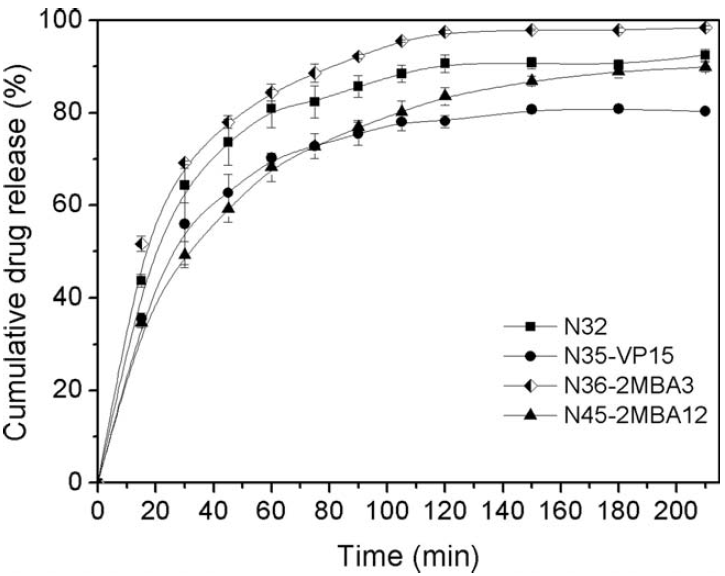

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Información general

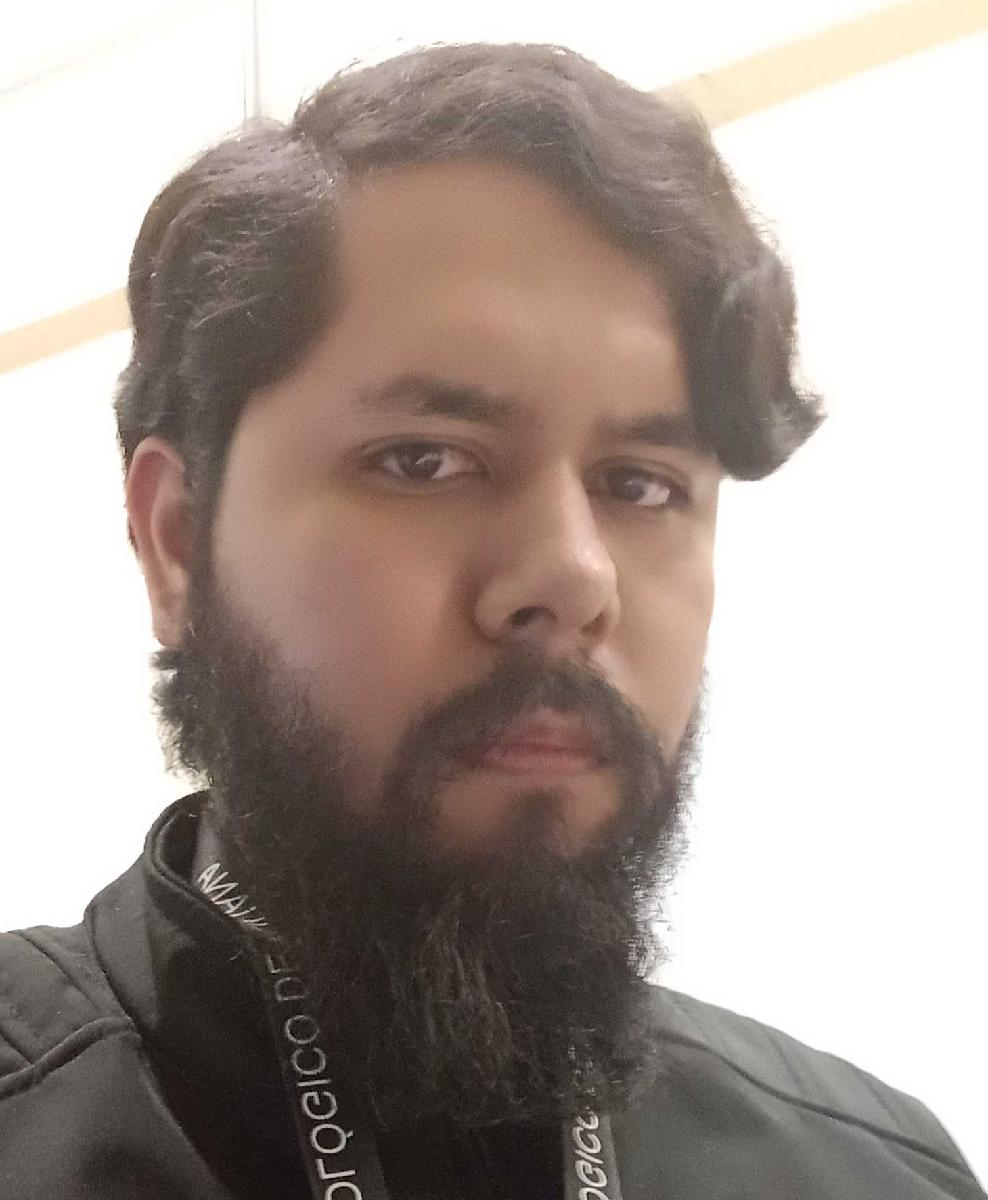

Nombre del alumno: **Vincent Alejandro Villela Salinas**

Número de control: **M25210045**

Correo institucional: **M25210045@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = \frac{\rho_{1}t}{\rho_{2}+t}$ $

Eureqa EDO: $$\dot{x} = \rho_{1} - \rho_{2}x_{1}$ $

## Datos experimentales

     t      N45       N32       N35       N36  
    ___    ______    ______    ______    ______

      0         0         0         0         0
     15    33.532    43.056    35.119    51.389
     30    48.611    63.889    55.556    68.452
     45    58.532    73.214    62.302    77.381
     60    67.857    80.556    69.841     83.73
     75    72.222    81.944    72.421    88.095
     90    76.389    85.317        75    91.667
    105    79.563    88.095    77.579     95.04
    120    82.937    90.278    77.778    97.024
    150     86.31    90.476    80.357    97.619
    180    88.294    90.079    80.357    97.421
    210    89.286    92.262     79.96    98.016



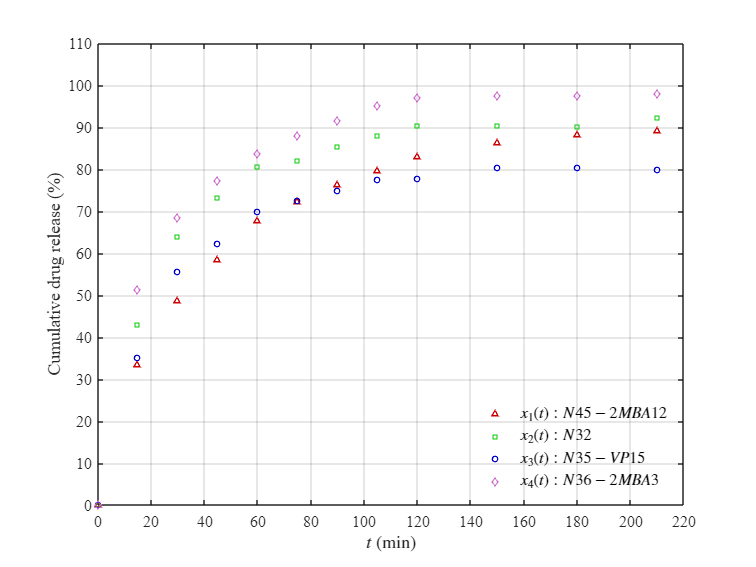

clc; clear; close all; warning('off')
[t,x1,x2,x3,x4] = getdata('data.csv');
plotdata(t,x1,x2,x3,x4); exportgraphics(gcf,'data.pdf','ContentType','vector')

### Regresión no lineal, bioestadísticos y experimentación in silico

labels = {'x1(t):N45-2MBA12','x2(t):N32','x3(t):N35-VP15','x4(t):N36-NMB3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Peppas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0,k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}       0.32034     0.027227    0.060666    0.25967      0.381    3.5168e-07
      {'n'}        17.232        2.204      4.9108     12.322     22.143    1.4383e-05

R-cuadrada ordinaria: 0.9785
R-cuadrada ajustada: 0.97635
Suma residual de cuadrados: 168.417
Criterio de información de Akaike: 69.753
Criterio de información de Akaike ajustado (n/k<40): 71.0863

    "Resultados para el hidrogel: "    "x2(t):N32"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}       0.22197     0.030697    0.068397    0.15358    0.29037    2.8203e-05
      {'n'}        30.063       4.2661      9.5054     20.558     39.568    3.5113e-05

R-cuadrada ordinaria: 0.96278
R-cuadrada ajustada: 0.95906
Suma residual de cuadrados: 301.1694
Criterio de información de Akaike: 76.7277
Criterio de información de Akaike ajustado (n/k<40): 78.0611

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}       0.23683     0.033814    0.075343    0.16149    0.31218    3.6979e-05
      {'n'}        24.523       3.8433      8.5635      15.96     33.087     8.028e-05

R-cuadrada ordinaria: 0.9573
R-cuadrada ajustada: 0.95303
Suma residual de cuadrados: 273.0552
Criterio de información de Akaike: 75.5517
Criterio de información de Akaike ajustado (n/k<40): 76.8851

    "Resultados para el hidrogel: "    "x4(t):N36-NMB3"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}       0.21189     0.024111    0.053722    0.15817    0.26561    5.1238e-06
      {'n'}        33.824       3.7632      8.3848     25.439     42.208    4.1875e-06

R-cuadrada ordinaria: 0.97587
R-cuadrada ajustada: 0.97346
Suma residual de cuadrados: 217.4251
Criterio de información de Akaike: 72.8179
Criterio de información de Akaike ajustado (n/k<40): 74.1512

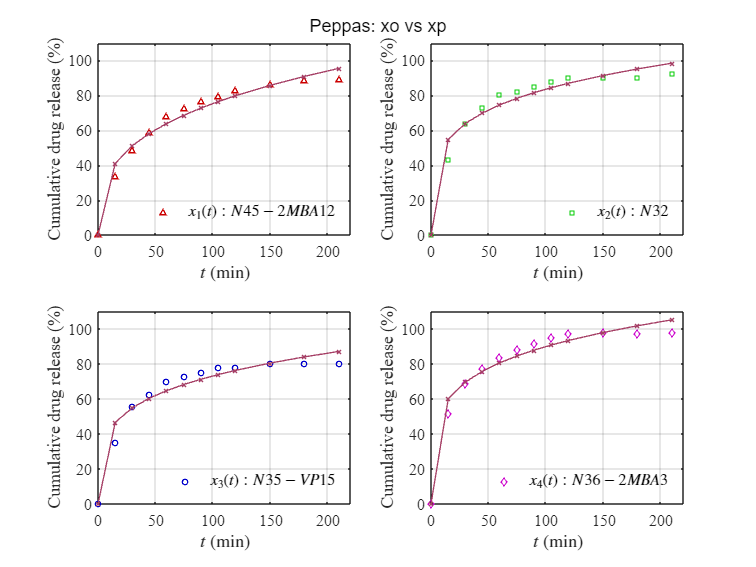

plotresults(t,xo,xp); sgtitle('Peppas: xo vs xp');...
    exportgraphics(gcf,'peppas.pdf','ContentType','vector')

### Función farmacocinética de primer orden

beta = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = farmacocinetica(t,xo(:,i),[beta,k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         87.345       1.3724       3.0578      84.287      90.403    2.2309e-14
      {'n'}       0.025654    0.0014099    0.0031414    0.022513    0.028796    5.3953e-09

R-cuadrada ordinaria: 0.99224
R-cuadrada ajustada: 0.99147
Suma residual de cuadrados: 60.7831
Criterio de información de Akaike: 57.5234
Criterio de información de Akaike ajustado (n/k<40): 58.8567

    "Resultados para el hidrogel: "    "x2(t):N32"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         89.687      0.81251       1.8104      87.876      91.497    9.1296e-17
      {'n'}       0.039961    0.0016905    0.0037667    0.036195    0.043728     4.164e-10

R-cuadrada ordinaria: 0.99554
R-cuadrada ajustada: 0.99509
Suma residual de cuadrados: 36.1041
Criterio de información de Akaike: 51.2725
Criterio de información de Akaike ajustado (n/k<40): 52.6059

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         79.143      0.65662        1.463       77.68      80.606    3.7907e-17
      {'n'}       0.037183    0.0013752    0.0030641    0.034119    0.040247    1.1073e-10

R-cuadrada ordinaria: 0.99656
R-cuadrada ajustada: 0.99621
Suma residual de cuadrados: 22.0094
Criterio de información de Akaike: 45.3333
Criterio de información de Akaike ajustado (n/k<40): 46.6666

    "Resultados para el hidrogel: "    "x4(t):N36-NMB3"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

      {'k'}          95.74      1.3926       3.1029      92.637      98.843    1.0332e-14
      {'n'}       0.041598    0.002899    0.0064594    0.035139    0.048058    5.3509e-08

R-cuadrada ordinaria: 0.9878
R-cuadrada ajustada: 0.98658
Suma residual de cuadrados: 109.9296
Criterio de información de Akaike: 64.6337
Criterio de información de Akaike ajustado (n/k<40): 65.9671

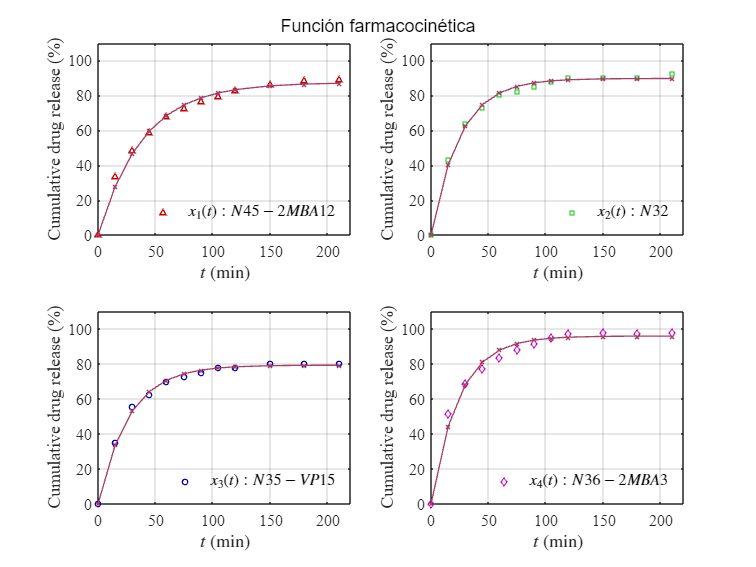

plotresults(t,xo,xfc); sgtitle('Función farmacocinética');...
    exportgraphics(gcf,'farmacocinetica.pdf','ContentType','vector')

### Eureqa: Función en el tiempo

rho1 = 105; rho2 = 33.5; xef = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = eureqafunction(t,xo(:,i),[rho1;rho2]);
    xef(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

      {'k'}        104.87     0.9059    2.0185    102.85    106.89    5.6725e-17
      {'n'}        33.665     1.0358    2.3079    31.357    35.973    1.7919e-11

R-cuadrada ordinaria: 0.99905
R-cuadrada ajustada: 0.99895
Suma residual de cuadrados: 7.4751
Criterio de información de Akaike: 32.3745
Criterio de información de Akaike ajustado (n/k<40): 33.7078

    "Resultados para el hidrogel: "    "x2(t):N32"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

      {'k'}        102.05      1.282    2.8566    99.189     104.9    2.3936e-15
      {'n'}        18.306     1.1333    2.5251    15.781    20.831    1.7129e-08

R-cuadrada ordinaria: 0.99645
R-cuadrada ajustada: 0.99609
Suma residual de cuadrados: 28.7522
Criterio de información de Akaike: 48.5402
Criterio de información de Akaike ajustado (n/k<40): 49.8735

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

      {'k'}        90.834     1.4134    3.1493    87.685    93.984    2.0252e-14
      {'n'}        20.314     1.4707     3.277    17.037    23.591    7.7034e-08

R-cuadrada ordinaria: 0.99504
R-cuadrada ajustada: 0.99454
Suma residual de cuadrados: 31.7328
Criterio de información de Akaike: 49.7239
Criterio de información de Akaike ajustado (n/k<40): 51.0572

    "Resultados para el hidrogel: "    "x4(t):N36-NMB3"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate      SE        MoE            CI95            Pvalue  
    __________    ________    _______    ______    ________________    __________

      {'k'}        108.07     0.98576    2.1964    105.87    110.27    9.7733e-17
      {'n'}        16.897     0.79427    1.7697    15.127    18.667    1.1725e-09

R-cuadrada ordinaria: 0.99798
R-cuadrada ajustada: 0.99777
Suma residual de cuadrados: 18.2336
Criterio de información de Akaike: 43.0748
Criterio de información de Akaike ajustado (n/k<40): 44.4082

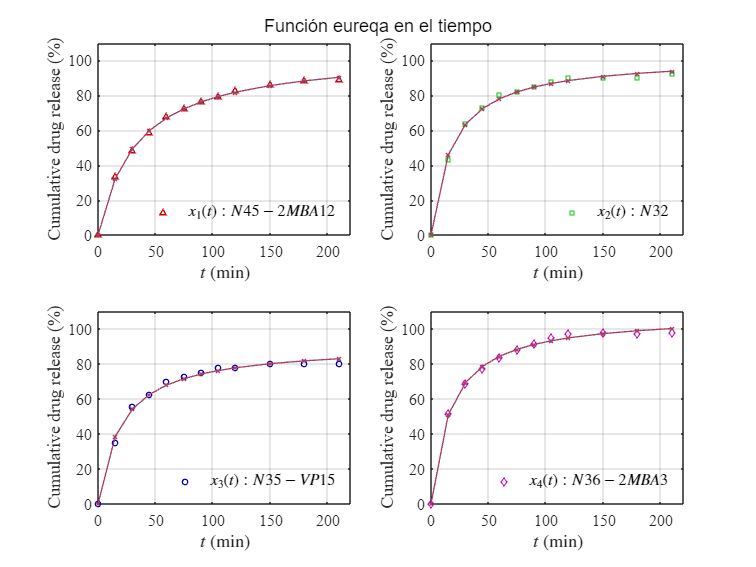

plotresults(t,xo,xef); sgtitle('Función eureqa en el tiempo');...
    exportgraphics(gcf,'eureqa_tiempo.pdf','ContentType','vector')

### Eureqa: Ecucación diferencial primer orden

rho1 = 2.25; rho2 = 0.0246; xef = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = eureqaODE(t,xo(:,i),[rho1;rho2]);
    xef(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         2.2395     0.099899      0.22259      2.0169      2.4621    7.0133e-10
      {'n'}       0.025632    0.0014232    0.0031711    0.022461    0.028803    5.9625e-09

R-cuadrada ordinaria: 0.99217
R-cuadrada ajustada: 0.99138
Suma residual de cuadrados: 61.3635
Criterio de información de Akaike: 57.6374
Criterio de información de Akaike ajustado (n/k<40): 58.9708

    "Resultados para el hidrogel: "    "x2(t):N32"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         3.586       0.13927      0.31031      3.2757      3.8963    1.7933e-10
      {'n'}       0.03998     0.0017596    0.0039207    0.036059      0.0439    6.1484e-10

R-cuadrada ordinaria: 0.99547
R-cuadrada ajustada: 0.99502
Suma residual de cuadrados: 36.6169
Criterio de información de Akaike: 51.4418
Criterio de información de Akaike ajustado (n/k<40): 52.7751

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         2.9481     0.099856      0.22249      2.7256      3.1706    4.6426e-11
      {'n'}       0.037252    0.0014433    0.0032159    0.034036    0.040468    1.7522e-10

R-cuadrada ordinaria: 0.99653
R-cuadrada ajustada: 0.99618
Suma residual de cuadrados: 22.1821
Criterio de información de Akaike: 45.4271
Criterio de información de Akaike ajustado (n/k<40): 46.7604

    "Resultados para el hidrogel: "    "x4(t):N36-NMB3"



Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}        4.0168       0.24318      0.54184       3.475      4.5587    1.3802e-08
      {'n'}       0.04199     0.0028619    0.0063766    0.035614    0.048367    4.3221e-08

R-cuadrada ordinaria: 0.98782
R-cuadrada ajustada: 0.9866
Suma residual de cuadrados: 109.808
Criterio de información de Akaike: 64.6204
Criterio de información de Akaike ajustado (n/k<40): 65.9538

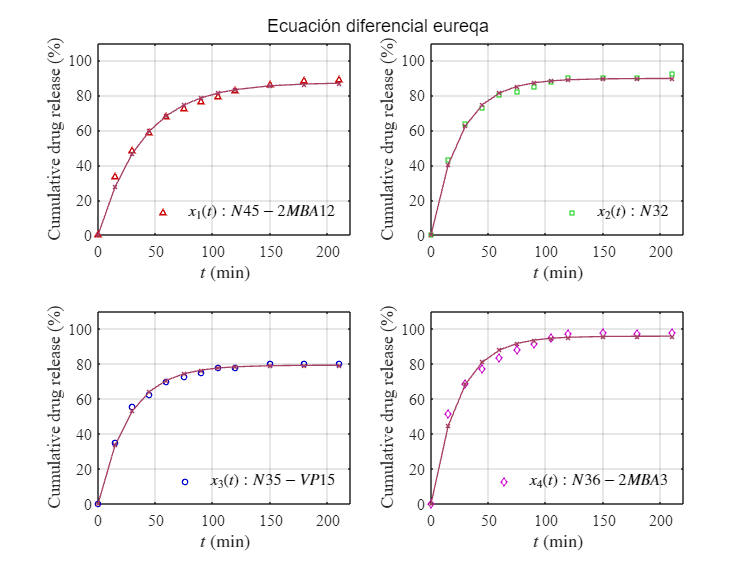

plotresults(t,xo,xef); sgtitle('Ecuación diferencial eureqa');...
    exportgraphics(gcf,'eureqa_ODE.pdf','ContentType','vector')

## Funciones

function [t,x1,x2,x3,x4] = getdata(file)
    sys = readmatrix(file);
    t = round(sys(:,1));
    x1 = sys(:,2);
    x2 = sys(:,3);
    x3 = sys(:,4);
    x4 = sys(:,5);
end

function plotdata(t,x1,x2,x3,x4)
    disp(array2table([t,x1,x2,x3,x4],VariableNames=["t" "N45" "N32" "N35" "N36"]))
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    hold on; box on; grid on;
    plot(t,x1,'^','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0])
    plot(t,x2,'square','LineWidth',1,'MarkerSize',4,'Color',[0,0.8,0])
    plot(t,x3,'o','LineWidth',1,'MarkerSize',4,'Color',[0,0,0.8])
    plot(t,x4,'d','LineWidth',1,'MarkerSize',4,'Color',[0.8,0.4,0.8])
    L = legend({'$x_{1}(t):N45-2MBA12$','$x_{2}(t):N32$','$x_{3}(t):N35-VP15$','$x_{4}(t):N36-2MBA3$'});
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off','Orientation','vertical')
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release (%)','Interpreter','Latex','FontSize',FS)
    xlim([0 220])
    ylim([0 110])
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function mdl = peppas(to,yo,Po)
    
    function fa = model(pa,t)
        n = pa(1);
        k = pa(2);
        fa = k*(t.^n);
    end
    parameters = {'k';'n'};
    mdl = fitnlm(to,yo,@model,Po);
    biostats(mdl,parameters)
end

function mdl = farmacocinetica(t,yo,Po)
    
    function fa = model(pa,t)
        beta = pa(1);
        k = pa(2);
        fa = beta*(1-exp(-k*t));
    end
    parameters = {'k';'n'};
    mdl = fitnlm(t,yo,@model,Po);
    biostats(mdl,parameters)
end

function mdl = eureqafunction(t,yo,Po)
    
    function fa = model(pa,t)
        rho1 = pa(1);
        rho2 = pa(2);
        fa = (t.*rho1)./(t+rho2);
    end
    parameters = {'k';'n'};
    mdl = fitnlm(t,yo,@model,Po);
    biostats(mdl,parameters)
end

function mdl = eureqaODE(t,yo,Po)
    x0 = yo(1);
    function fa = model(pa,tspan)
        rho1 = pa(1);
        rho2 = pa(2);
        f = @(t,x) rho1 - rho2*x;
        [tsim,xsim] = ode45(f,[min(tspan) max(tspan)],x0);
        fa = interp1(tsim,xsim,tspan,'linear');
    end
    parameters = {'k';'n'};
    mdl = fitnlm(t,yo,@model,Po);
    biostats(mdl,parameters)
end

function biostats(mdl,Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['Degrees of freedom: ',num2str(dof)])
    disp(['t-student value: ',num2str(tval)])
    disp(['Significance value (alpha): ',num2str(alpha)])
    disp(' '); disp(Results)
    R2o = mdl.Rsquared.Ordinary;
    R2a = mdl.Rsquared.Adjusted;
    SSE = mdl.SSE;
    AIC = mdl.ModelCriterion.AIC;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);...
    fprintf(['\nR-cuadrada ajustada: ', num2str(R2a)]);...
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);...
    fprintf(['\nCriterio de información de Akaike: ', num2str(AIC)]);...
    fprintf(['\nCriterio de información de Akaike ajustado (n/k<40): ', num2str(AICc)]);
end

function plotresults(t,xo,xp)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(2,2,1)
    hold on; box on; grid on;
    plot(t,xo(:,1),'^','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0])
    plot(t,xp(:,1),'-x','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    L = legend({'$x_{1}(t):N45-2MBA12$'});
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off','Orientation','Horizontal')
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release (%)','Interpreter','Latex','FontSize',FS)
    xlim([0 220])
    ylim([0 110])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,2)
    hold on; box on; grid on;
    plot(t,xo(:,2),'square','LineWidth',1,'MarkerSize',4,'Color',[0,0.8,0])
    plot(t,xp(:,2),'-x','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    L = legend({'$x_{2}(t):N32$'});
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off','Orientation','Horizontal')
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release (%)','Interpreter','Latex','FontSize',FS)
    xlim([0 220])
    ylim([0 110])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,3)
    hold on; box on; grid on;
    plot(t,xo(:,3),'o','LineWidth',1,'MarkerSize',4,'Color',[0,0,0.8])
    plot(t,xp(:,3),'-x','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    L = legend({'$x_{3}(t):N35-VP15$'});
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off','Orientation','vertical')
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release (%)','Interpreter','Latex','FontSize',FS)
    xlim([0 220])
    ylim([0 110])
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,4)
    hold on; box on; grid on;
    plot(t,xo(:,4),'d','LineWidth',1,'MarkerSize',4,'Color',[0.8,0,0.8])
    plot(t,xp(:,4),'-x','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    L = legend({'$x_{4}(t):N36-2MBA3$'});
    set(L,'Interpreter','Latex','FontSize',FS,'Location','southeast','Box','Off','Orientation','vertical')
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release (%)','Interpreter','Latex','FontSize',FS)
    xlim([0 220])
    ylim([0 110])
    set(gca,'FontName','Times New Roman','FontSize',FS)
end